## Cycle Freq Analysis

% Set path for data dirs
DataDir1 = 'D:\cleaned_EEG_Data'; % eeg data
DataDir2 = 'D:\CODE_SCRIPTS\Data_Analysis\EEG_Time_scripts'; % chan info
DataDir3 = 'D:\CODE_SCRIPTS\sweep_data_a\rcaExtra' ; % functions from SVNDL
addpath(DataDir1) ; addpath(DataDir2) ; addpath(DataDir3)

## import data to pick best electrodes

cd(DataDir2)
run('SubjElec_Chans.m');
f1_chans = UniqElecInfo.F1;
f2_chans = UniqElecInfo.F2;

## Set path where EEG data exists 

cd(DataDir1) % set working directory
disp(pwd)

D:\cleaned_EEG_Data


%EEG_Data_All = load('clean_data_all.mat'); % import cleaned data
%EEG_Data_All = load('clean_data_all_wF1Filt.mat'); % import cleaned data
EEG_Data_All = load('clean_data_all_wNFSigFilt.mat'); % import cleaned data

## Params

cond = 1; % conditions
BinTimeinSecs = 2 ; % bin duration in seconds
NumBins = 5; % number of bins
NumEps = 2; % # times we want to analyze data in pre / post manner
T1 = [1,  31] ; % start inds
T2 = [30, 60]; % end inds
EOI = f2_chans;% 70:1:72; % electrodes of interest to average across can be: [] too
DAQ = 420; % sampling rate
[nSamps, nChans, nTrials] = size(EEG_Data_All.nFSignal{1});  % dims of data
Fx = 2; %frequency to pick (2 ops) : F1 = 1.5 Hz, F2 = 2 Hz %

## Math to Find Samps per Cycle of a Frequency

TotalSampsPerDur = DAQ * BinTimeinSecs; % total samples per bin
SampsPerSingleCycle = DAQ / Fx; % # of samples for a single freq cycle
NumCycles = (TotalSampsPerDur/ SampsPerSingleCycle) * 2; % #cycles per bin
NumSamps = TotalSampsPerDur / NumCycles ; % # of samples for 1 cycle dur
NumRows = (nSamps/NumBins) / NumSamps; % rows to account for each binned time array
BinEnd = TotalSampsPerDur : TotalSampsPerDur : nSamps;
BinInit = (BinEnd - (TotalSampsPerDur-1));
cycle_init = BinInit: NumSamps : TotalSampsPerDur;
cycle_end = cycle_init + (NumSamps-1);
%legend_hands = {'pre','post'};

%%%% for many electrodes %%%%%%%%% (more than 1 electrode indexed)
%cycle_data = zeros(NumRows,NumSamps,size(EOI,2)); % empty data matrix

%%%% for single best electrode %%%%%% (the best electrode indexed)
cycle_data = zeros(NumRows,NumSamps,size(EOI,1));

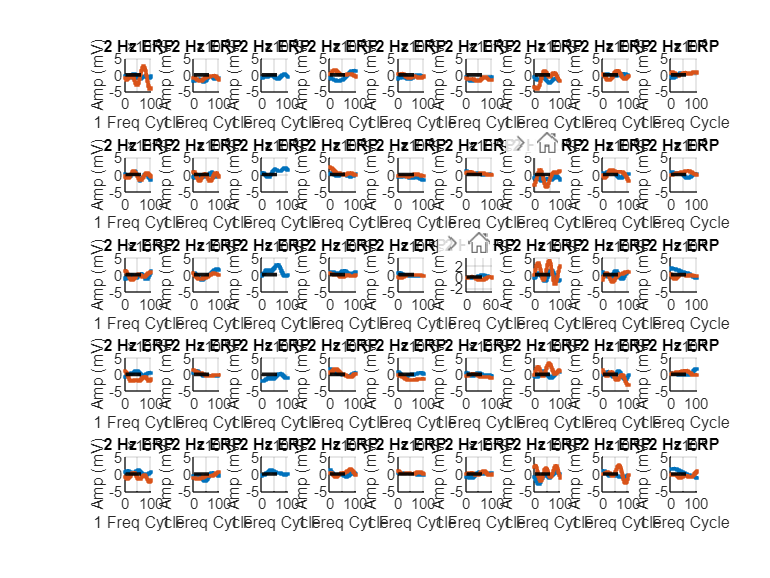

counter = 1; % for plots
figure;
for bin = 1:size(BinEnd,2) % iterate for all 5 contrast increments
    for subs = 1:size(EEG_Data_All.nFSignal,1) % iterate for all subjects 
        %fullFilePath = fileNames{subs}; % subject file name
        data = EEG_Data_All.nFSignal{subs}; % import file with that name
        eeg_data = data(BinInit(bin):BinEnd(bin),:,:);
        subplot(NumBins,size(EEG_Data_All.nFSignal,1),counter) % plot
        counter = counter + 1;
            for trial_ind = 1:NumEps % binned data within this time interval to average a number of electrodes
                %%%%% for many electrodes
                %data_ind = mean(eeg_data(:,EOI,T1(trial_ind):T2(trial_ind)),3,'omitnan');  
                % data index for one single elctrode (the best per subject)
                %%%%% for one single electrode
                data_ind = mean(eeg_data(:,EOI(subs),T1(trial_ind):T2(trial_ind)),3,'omitnan');
                    for row = 1:NumRows % store mini bins
                        cycle_data(row,:,:) = data_ind(cycle_init(bin):cycle_end(bin),:);
                    end
                erp = mean(mean(cycle_data,1,'omitnan'),3); %compute avg
                plot(erp, 'LineWidth', 1.5,'Marker','.') % plot data result
                %legend(legend_hands)
                yline(0, 'k--', 'LineWidth', 2);
                grid on; hold on; box off;
                titleString = [num2str(Fx), ' Hz ERP'];
                title(titleString)
                xlabel('1 Freq Cycle'); ylabel('Amp (mV)');
                yMax = 5 * 10^(-6);
                yMin = -5 * 10^(-6);
                ylim([yMin,yMax]);
                set(gcf,'color','w'); shg
            end
            hold off;
    end
end

## pin for wokr computer 0808